# Power reference tracking

clear all; clc; close all;

## Import the data

tdms = TDMS_getStruct('step1.tdms')

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


measurements = tdms.Group1;
m(:).control = measurements.Control.data;
m(:).time = measurements.Time.data;
m(:).I_stack  = measurements.I_Stack.data;
m(:).U_stack = measurements.U_Stack.data;
m(:).T_in = measurements.O2_T_In.data;
m(:).T_out = measurements.O2_T_Out.data;
m(:).tankP = measurements.H2_PrProd.data;

m(:).T = (m.T_in+m.T_out)./2; %find average stack temperature

### Plot the experiment

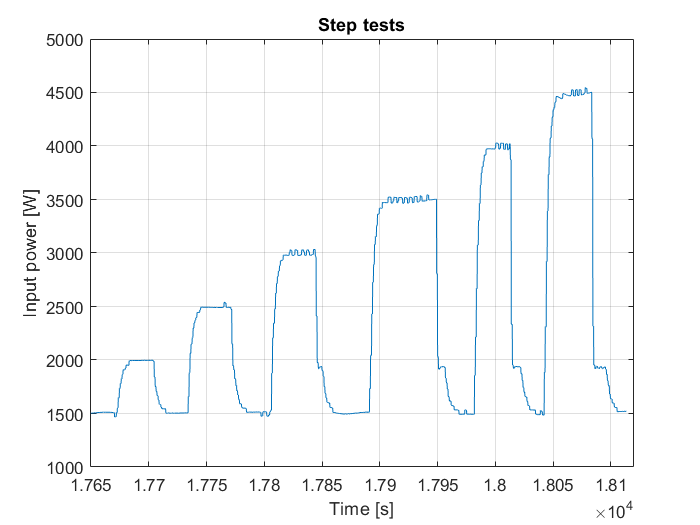

figure;
plot(m.time(1250:3600),m.I_stack(1250:3600).*m.U_stack(1250:3600))
ylabel("Input power [W]")
xlabel("Time [s]")
title("Step tests")
grid on
xlim([17650 18120])

### Interpolate & plot

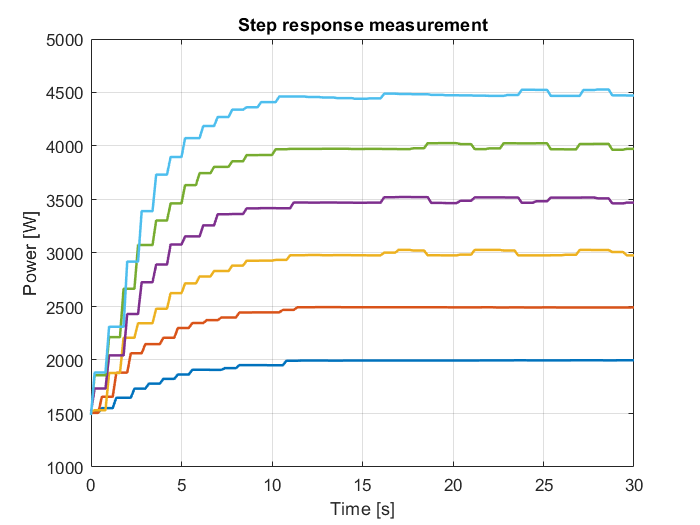

startindexes = [1394, 1701, 2060, 2488, 2942, 3244];
target_P = [2000, 2500, 3000, 3500, 4000, 4500];
initial_P = [ones(1,6).*1500];
interp_step = 5;
stab = 150;
slice = 1:interp_step:stab+1;
steps.times = zeros(6,stab+1);
steps.U = zeros(6,stab+1);
steps.I = zeros(6,stab+1);
for ind = 1:length(startindexes)
    time = m.time(startindexes(ind):startindexes(ind)+stab) - m.time(startindexes(ind)); 
    U = m.U_stack(startindexes(ind):startindexes(ind)+stab);
    I = m.I_stack(startindexes(ind):startindexes(ind)+stab);
    steps.times(ind,:) = interp1(time(slice),time(slice), time);
    steps.U(ind,:) = interp1(time(slice), U(slice), time); 
    steps.I(ind,:) = interp1(time(slice), I(slice), time);
    steps2.times(ind,:) = time;
    steps2.U(ind,:) = U;    
    steps2.I(ind,:) = I;
end
steps.Pin = steps.U .* steps.I;
steps2.Pin = steps2.U .* steps2.I;
figure;
plot(steps2.times',steps2.Pin',"linewidth",1.5)
title("Step response measurement")
ylabel("Power [W]")
xlabel("Time [s]")
xlim([0 ,30])
grid on

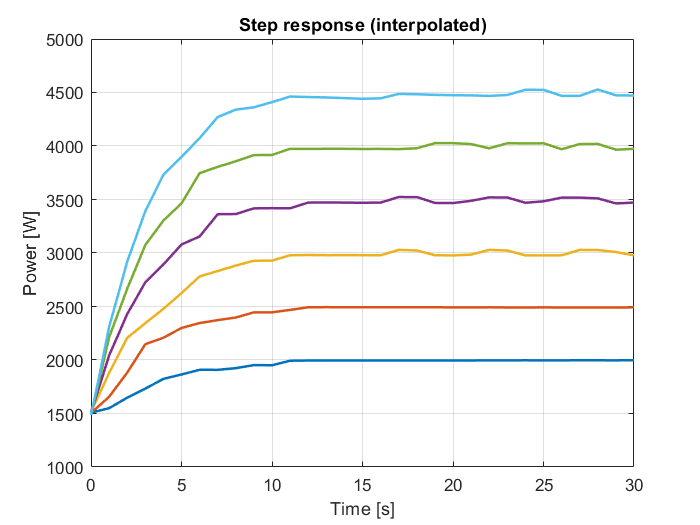

figure;
plot(steps.times',steps.Pin',"linewidth",1.5)
grid on
title("Step response (interpolated)")
ylabel("Power [W]")
xlabel("Time [s]")
xlim([0 ,30])

### OLS regression for tau

taus = zeros(1,length(startindexes));
for i = 1:length(startindexes)
    Ts = mean(diff(steps.times(i,:)));
    y = steps.Pin(i,:);
    ydiff = diff(y);
    taus(i) = first_order_tau_estimator(y(2:end),ydiff,Ts,initial_P(i),target_P(i));
end
tau = mean(taus);

### Plot with the estimated tau

figure;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



model = 1/(1+tau*s)

model =
 
       1
  -----------
  3.039 s + 1
 
Continuous-time transfer function.



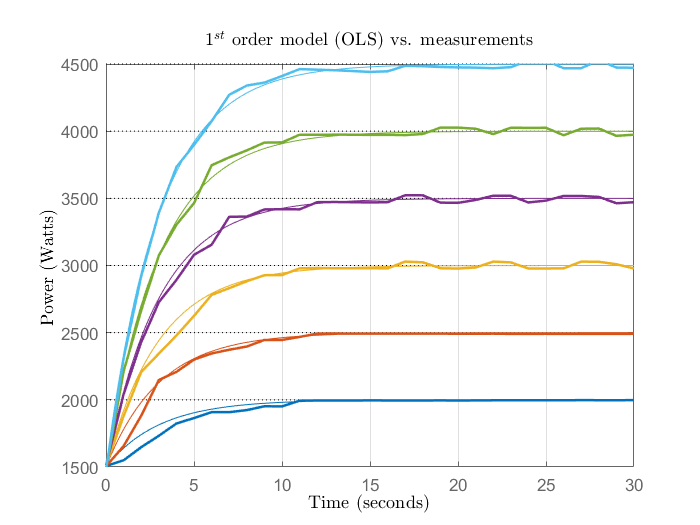

    opt = stepDataOptions;
    opt.InputOffset = 1500;
for jump = target_P-initial_P
    opt.StepAmplitude = jump;
    hold on
    step(model, opt)
    hold off
end
grid on
hold on
plot(steps.times',steps.Pin',"linewidth",1.5)
hold off
title("$1^{st}$ order model (OLS) vs. measurements","Interpreter","latex")
xlabel("Time","Interpreter","latex")
ylabel("Power (Watts)","interpreter","latex")

## Tau - threshold method

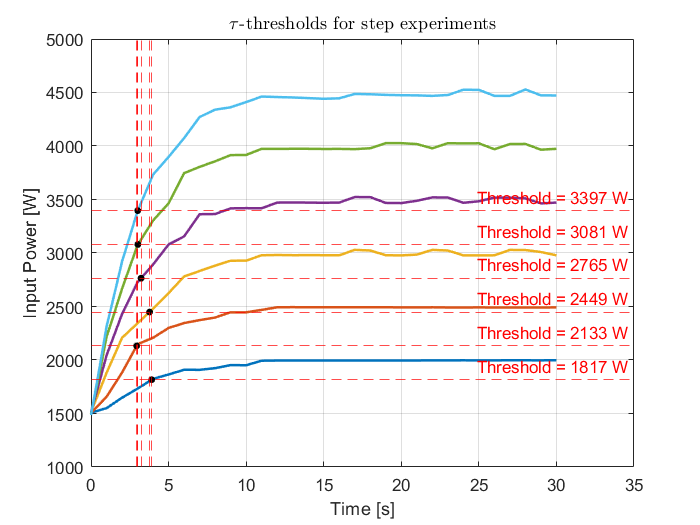

figure;
threshold = initial_P + (target_P-initial_P).*0.63205;
over = steps.Pin > threshold';
firstpass  = ones(1,6);
for i = 1:length(startindexes)
    firstpass(i) =  find(over(i,:),1);
end
idxup = sub2ind(size(steps.times), 1:6, firstpass);
idxdown = sub2ind(size(steps.times), 1:6, firstpass-1);
t1 = steps.times(idxdown);
p1 = steps.Pin(idxdown);
t2 = steps.times(idxup);
p2 = steps.Pin(idxup);
pth = threshold;

tt = (t2.*(pth-p1) + t1.*(p2-pth))./(p2-p1);

plot(steps.times',steps.Pin',"linewidth",1.5)
hold on
scatter(tt,pth,200,".k")
hold off
grid on
ylabel("Input Power [W]")
xlabel("Time [s]")
title("$\tau$-thresholds for step experiments","Interpreter","latex")

for th = 1:length(threshold)
    yline(threshold(th),"--r",{"Threshold = " + num2str(ceil(threshold(th))) + " W"})
    xline(tt(th),"--r")
end
tau = mean(tt);
hold off

### Plot with the estimated tau

figure;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



model = 1/(1+tau*s)

model =
 
       1
  -----------
  3.315 s + 1
 
Continuous-time transfer function.



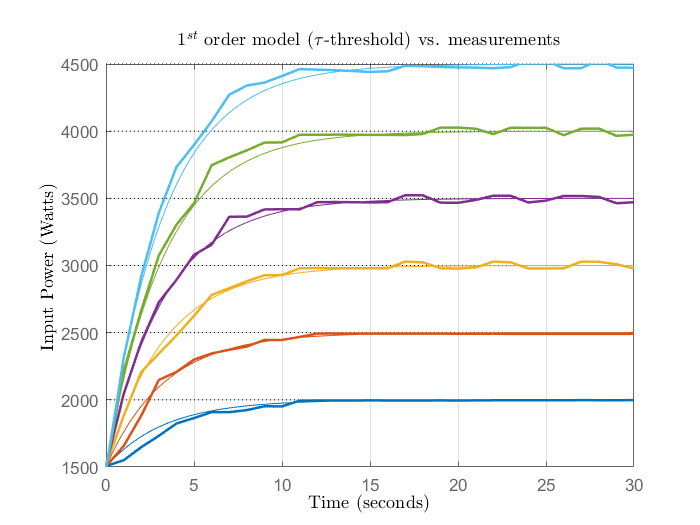

    opt = stepDataOptions;
    opt.InputOffset = 1500;
for jump = target_P-initial_P
    opt.StepAmplitude = jump;
    hold on
    step(model, opt)
    hold off
end
grid on
hold on
plot(steps.times',steps.Pin',"linewidth",1.5)
hold off
title("$1^{st}$ order model ($\tau$-threshold) vs. measurements","Interpreter","latex")
    
xlabel("Time","interpreter","latex")
ylabel("Input Power (Watts)","interpreter","latex")

## Negative step

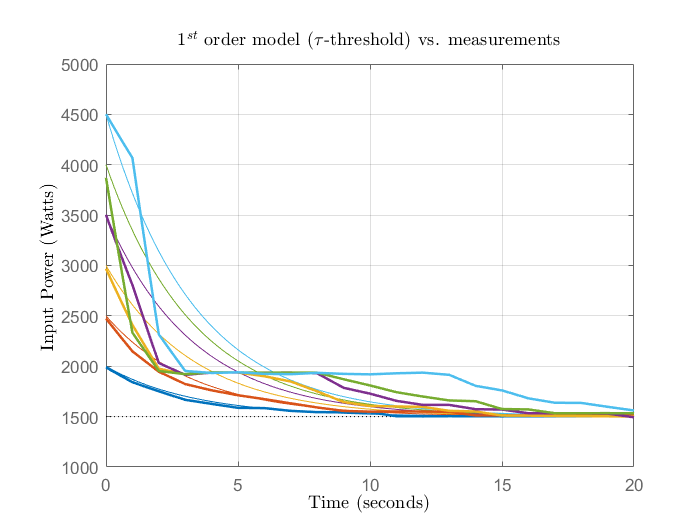

figure;
startindexes = [1554, 1890, 2255, 2776, 3099, 3448];
initial_P = [2000, 2500, 3000, 3500, 4000, 4500];
target_P = [ones(1,6).*1500];
stab = 150;
steps.times = zeros(6,stab+1);
steps.U = zeros(6,stab+1);
steps.I = zeros(6,stab+1);
for ind = 1:length(startindexes)
 time = m.time(startindexes(ind):startindexes(ind)+stab) - m.time(startindexes(ind)); 
    U = m.U_stack(startindexes(ind):startindexes(ind)+stab);
    I = m.I_stack(startindexes(ind):startindexes(ind)+stab);
    steps.times(ind,:) = interp1(time(slice),time(slice), time);
    steps.U(ind,:) = interp1(time(slice), U(slice), time); 
    steps.I(ind,:) = interp1(time(slice), I(slice), time);
end
steps.Pin = steps.U .* steps.I;
opt = stepDataOptions;
for jump = target_P-initial_P
    opt.InputOffset = 1500 + abs(jump);
    opt.StepAmplitude = jump;
    hold on
    step(model, opt)
    hold off
end
grid on
hold on
plot(steps.times',steps.Pin',"linewidth",1.5)
hold off
xlim([0 20])
title("$1^{st}$ order model ($\tau$-threshold) vs. measurements","Interpreter","latex")
    
xlabel("Time","interpreter","latex")
ylabel("Input Power (Watts)","interpreter","latex")